syms f x
f = cos(x);
taylor(f,x,'Order',9)

$$ans = \frac{x^{8}}{40320}-\frac{x^{6}}{720}+\frac{x^{4}}{24}-\frac{x^{2}}{2}+1$$

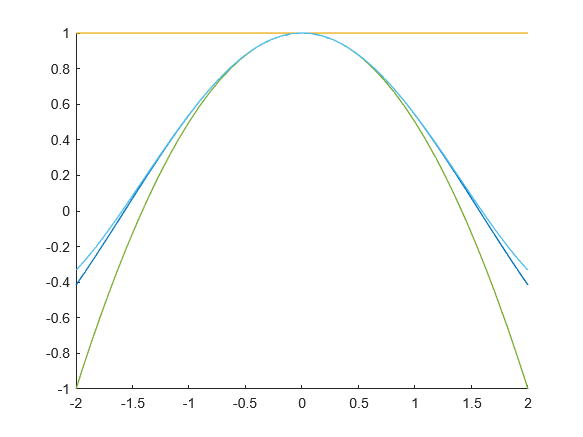

true_cos = cos(pi/12);

% a)
T1f = taylor(f,x,'Order',1);
T2f = taylor(f,x,'Order',2);
T3f = taylor(f,x,'Order',3);
T4f = taylor(f,x,'Order',4);
T5f = taylor(f,x,'Order',5);

figure
hold on
fplot([f,T1f,T2f,T3f,T4f,T5f],[-2,2])
hold off


% b)
aprox_cos = 0;
for k=0:5
    term = ((-1)^k) * (pi/12)^(2*k) / factorial(2*k);
    aprox_cos = aprox_cos + term;
end

fprintf('True value of cos(pi/12): %.25f\n', true_cos);

True value of cos(pi/12): 0.9659258262890683122137148


fprintf('Aprox value of cos(pi/12): %.25f\n', aprox_cos);

Aprox value of cos(pi/12): 0.9659258262890682011914123



% abs(true_cos-aprox_cos)%eroare

% c)
aprox_cos = 0;
for k=0:5
    term = ((-1)^k) * (pi/12)^(2*k) / factorial(2*k);
    aprox_cos = aprox_cos + term;
    if abs(true_cos-aprox_cos) < 1e-5
        termeni=k;
        break
    end
end

termeni

termeni = 2

fprintf('True value of cos(pi/12): %.25f\n', true_cos);

True value of cos(pi/12): 0.9659258262890683122137148


fprintf('Aprox value of cos(pi/12): %.25f\n', aprox_cos);

Aprox value of cos(pi/12): 0.9659262729189806995222511


abs(true_cos-aprox_cos)%eroare

ans = 4.4663e-07